clear variables; close all; clc;
base_path = "/home/achadbo/XPlaneAutolandScenario";
err_path = base_path + "/errors";
plot_path = base_path + "/plots";
date = "/2024-4-23";
gen = "/generated_states.csv";
com = "/combined_states.csv";

csvData0_g = readtable("/home/achadbo/XPlaneAutolandScenario/errors/2024-6-21/150/generated_states.csv")

csvData0_g = 67999×3 table
     y_err     h_err_NN    h_err_true
    _______    ________    __________

     67.772    -63.335      -13.746  
    -46.349     3.5223      -104.94  
     4.5007     3.2162      -6.1906  
     55.505    -56.113       2.2222  
     71.034     -27.88      -63.361  
     31.429    -56.687      -54.512  
    -48.632    -64.465        -77.4  
     60.031    -59.562      -109.13  
     62.497    -54.922       -92.34  
    -25.608     11.797      -152.14  
    -12.208    -0.8733        12.63  
    -22.751     11.899      -3.3539  
     25.166    -63.043       1.5638  
    -15.307     34.112      -116.18  
    -48.799    -67.838       19.548  
    -57.633    -72.458      -140.76  


csvData0_c = readtable("/home/achadbo/XPlaneAutolandScenario/plots/2024-6-21/150/combined_states.csv")

csvData0_c = 67999×8 table
    error_h    error_y      phi       theta       psi          x          y         h   
    _______    _______    _______    _______    ________    _______    _______    ______

    -49.589     6.2274     5.8376    -1.3007    -0.68804    -37.002     73.999    479.24
     108.46     -8.652    0.69297     6.3457     -8.5868    -99.001    -55.001    377.24
     9.4069    0.49793    -4.8731     6.5781      6.4781    -53.001     4.9986    371.24
    -58.336    0.49176     6.3923     6.0025     0.79073    -26.001     55.997    438.24
     35.481     44.963     2.2328     2.2367      1.5746    -67.002        116    427.24
    -2.1755    -1.4284    -3.6772      7.978      -1.249        145         3

error_NN_h_0 = csvData0_c.error_h

error_NN_h_0 =   -49.5893
  108.4595
    9.4069
  -58.3356
   35.4808
   -2.1755
   12.9355
   49.5677
   37.4185
  163.9408


error_NN_y_0 = csvData0_c.error_y

error_NN_y_0 =     6.2274
   -8.6520
    0.4979
    0.4918
   44.9632
   -1.4284
  -35.3685
    0.9670
   68.5023
    2.6077


y_pred_0 = csvData0_g.y_err

y_pred_0 =    67.7715
  -46.3492
    4.5007
   55.5055
   71.0344
   31.4286
  -48.6324
   60.0308
   62.4966
  -25.6076


h_pred_0 = csvData0_g.h_err_NN

h_pred_0 =   -63.3350
    3.5223
    3.2162
  -56.1134
  -27.8803
  -56.6872
  -64.4646
  -59.5620
  -54.9219
   11.7974


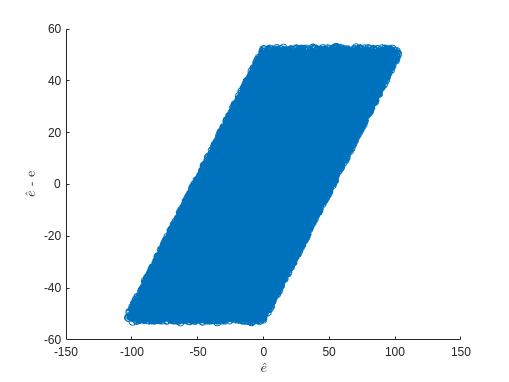



csvData50_g = readtable(err_path + "/2024-5-24/50/generated_states.csv"); %50m, OOD by 0
csvData50_c = readtable(plot_path + "/2024-5-24/50/combined_states.csv");

error_h_50 = csvData50_c.error_h; %NN Error, height offset 
error_y_50 = csvData50_c.error_y; %NN Error, crosstrack offset 
ehat_h_50 = csvData50_g.h_err_NN; %NN Output- Predicted height offset
ehat_y_50 = csvData50_g.y_err;

scatter(error_h_50, ehat_h_50);
hold on;
xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;

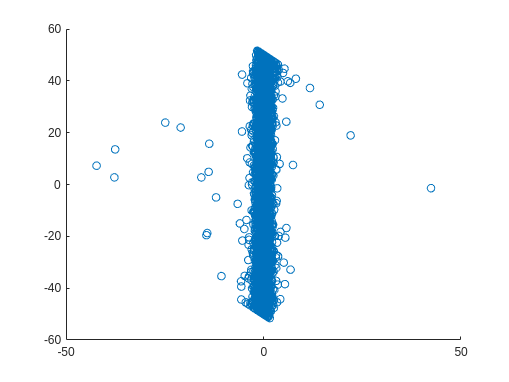


scatter(error_y_50, ehat_y_50);

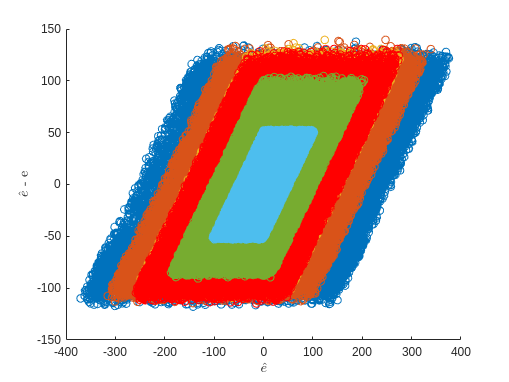


error_NN_h_50 = csvData50_c.error_h; %NN Error, height offset 
error_NN_y_50 = csvData50_c.error_y; %NN Error, crosstrack offset 
y_pred_50 = csvData50_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_50 = csvData50_g.h_err_NN; %NN Output- Predicted height offset
h_true_50 = csvData50_g.h_err_true; %True height error based on state info 

%True State Information 
x50 = csvData50_c.x; %Horizontal distance from runway 
h50 = csvData50_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData100_g = readtable(err_path + date + "/100" + gen);%100m, OOD by 50
csvData100_c = readtable(plot_path + date + "/100" + com);

error_NN_h_100 = csvData100_c.error_h; %NN Error, height offset 
error_NN_y_100 = csvData100_c.error_y; %NN Error, crosstrack offset 
y_pred_100 = csvData100_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_100 = csvData100_g.h_err_NN; %NN Output- Predicted height offset
h_true_100 = csvData100_g.h_err_true; %True height error based on state info 

%True State Information 
x100 = csvData100_c.x; %Horizontal distance from runway 
h100 = csvData100_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData150_g = readtable(err_path + date + "/150" + gen); %150m, OOD by 100
csvData150_c = readtable(plot_path + date + "/150" + com);

error_NN_h_150 = csvData150_c.error_h; %NN Error, height offset 
error_NN_y_150 = csvData150_c.error_y; %NN Error, crosstrack offset 
y_pred_150 = csvData150_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_150 = csvData150_g.h_err_NN; %NN Output- Predicted height offset
h_true_150 = csvData150_g.h_err_true; %True height error based on state info 

%True State Information 
x150 = csvData150_c.x; %Horizontal distance from runway 
h150 = csvData150_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData200_g = readtable(err_path + date + "/200" + gen); %200m, OOD by 150
csvData200_c = readtable(plot_path + date + "/200" + com);

error_NN_h_200 = csvData200_c.error_h; %NN Error, height offset 
error_NN_y_200 = csvData200_c.error_y; %NN Error, crosstrack offset 
y_pred_200 = csvData200_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_200 = csvData200_g.h_err_NN; %NN Output- Predicted height offset
h_true_200 = csvData200_g.h_err_true; %True height error based on state info 

%True State Information 
x200 = csvData200_c.x; %Horizontal distance from runway 
h200 = csvData200_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData250_g = readtable(err_path + date + "/250" + gen); %250m, OOD by 200
csvData250_c = readtable(plot_path + date + "/250" + com);

error_NN_h_250 = csvData250_c.error_h; %NN Error, height offset 
error_NN_y_250 = csvData250_c.error_y; %NN Error, crosstrack offset 
y_pred_250 = csvData250_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_250 = csvData250_g.h_err_NN; %NN Output- Predicted height offset
h_true_250 = csvData250_g.h_err_true; %True height error based on state info 

%True State Information 
x250 = csvData250_c.x; %Horizontal distance from runway 
h250 = csvData250_c.h; %True Height (Altitude relative to runway) 

%=======================================================================

csvData300_g = readtable(err_path + date + "/300" + gen); %300m, OOD by 250
csvData300_c = readtable(plot_path + date + "/300" + com);

error_NN_h_300 = csvData300_c.error_h; %NN Error, height offset 
error_NN_y_300 = csvData300_c.error_y; %NN Error, crosstrack offset 
y_pred_300 = csvData300_g.y_err; %NN Output- Predicted crosstrack offset 
h_pred_300 = csvData300_g.h_err_NN; %NN Output- Predicted height offset
h_true_300 = csvData300_g.h_err_true; %True height error based on state info 

%True State Information 
x300 = csvData300_c.x; %Horizontal distance from runway 
h300 = csvData300_c.h; %True Height (Altitude relative to runway) 

%=======================================================================
%=======================================================================

%2: Pinpoint the Graphs that we want to condense (Add photos of collected
%data from Notes to pdf) 
    %Most relevant graphs: 
        % Crosstrack Error NN vs Horizontal Distance from Runway 
        % Crosstrack Error NN vs True Height (Altitude relative to runway) 

        % Height Error NN vs Horizontal Distance from Runway 
        % Height Error NN vs True Height (Altitude relative to runway) 

    % Would be Interesting to explore (Not completed here) 
        % Crosstrack Error NN vs Predicted Crosstrack Offset (NN Output)
        % Height Error NN vs Predicted Height Offset (NN Output) 

%=======================================================================
%=======================================================================

%3: Create 3D scatter plots where x = distance, y = OOD and z = NN Error
%and condense 

%Fun Matrices: 
x = [x50; x100; x150; x200; x250; x300]; 
h = [h50; h100; h150; h200; h250; h300]; 
error_NN_h = [error_NN_h_50; error_NN_h_100; error_NN_h_150; error_NN_h_200; error_NN_h_250; error_NN_h_300];
error_NN_y = [error_NN_y_50; error_NN_y_100; error_NN_y_150; error_NN_y_200; error_NN_y_250; error_NN_y_300];
y_pred =  [y_pred_50; y_pred_100; y_pred_150; y_pred_200; y_pred_250; y_pred_300];
h_pred = [h_pred_50; h_pred_100; h_pred_150; h_pred_200; h_pred_250; h_pred_300];
h_true = [h_true_50; h_true_100; h_true_150; h_true_200; h_true_250; h_true_300];
zero = repelem(0, length(x50)); 
fifty = repelem(50, length(x100)); 
hundred = repelem(100, length(x150)); 
hundfif = repelem(150, length(x200)); 
weirdhundfif = repelem(150, length(csvData0_c.x)); 
twohun = repelem(200, length(x250)); 
twohunfif = repelem(250, length(x300)); 
ODD_m = [zero'; fifty'; hundred'; hundfif'; twohun'; twohunfif']; 

%Starting with the "most relevant"
%First we need to make a table for each plot (Doing this early in case it
%makes bounding easier)- it did not but I'll keep it in in case a blanket
%function is deemed appropriate 

% Crosstrack Error NN vs Horizontal Distance from Runway 
tab1 = table(x, ODD_m, error_NN_y);

% Crosstrack Error NN vs True Height (Altitude relative to runway) 
tab2 = table(h, ODD_m, error_NN_y);

% Height Error NN vs Horizontal Distance from Runway 
tab3 = table(x, ODD_m, error_NN_h);

% Height Error NN vs True Height (Altitude relative to runway) 
tab4 = table(h, ODD_m, error_NN_h);

%PLOTS + Condense 
%========================================================================================


scatter(error_NN_h_250, h_pred_250);
hold on; 
scatter(error_NN_h_200, h_pred_200);
scatter(error_NN_h_150, h_pred_150);
scatter(error_NN_h_0, h_pred_0, "red");
scatter(error_NN_h_100, h_pred_100);
scatter(error_NN_h_50, h_pred_50);

xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;

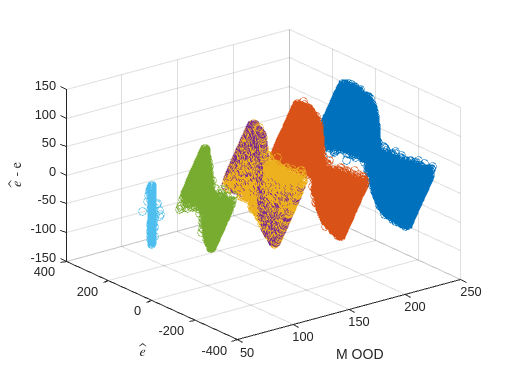





scatter3(twohunfif, error_NN_y_250, y_pred_250);

hold on; 
scatter3(twohun, error_NN_y_200, y_pred_200);
scatter3(weirdhundfif, error_NN_y_0, y_pred_0);
scatter3(repelem(150, length(csvData150_c.x)), error_NN_y_150, y_pred_150);
scatter3(hundred, error_NN_y_100, y_pred_100);
scatter3(fifty, error_NN_y_50, y_pred_50);

xlabel("M OOD")
ylabel('$$\hat{e}$$','Interpreter','Latex');
zlabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;

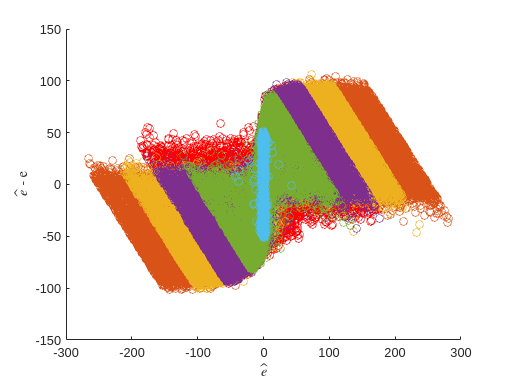




scatter(error_NN_y_0, y_pred_0, "red");

hold on; 
scatter(error_NN_y_250, y_pred_250);
scatter(error_NN_y_200, y_pred_200);
scatter(error_NN_y_150, y_pred_150);
scatter(error_NN_y_100, y_pred_100);
scatter(error_NN_y_50, y_pred_50);

xlabel('$$\hat{e}$$','Interpreter','Latex');
ylabel('$\hat{e}$ - e','Interpreter','Latex');
hold off;